# GCC-Phat 时延估计（相位实现）

## 载入数据

- 经过验证，确定提取信号位置在(1668:2580)为最优。

clear;
clc;
close all;
 
load('C:\Users\Exusisa\Desktop\time_delay\sim_deta\echo_unwrapping.mat') ;

rawdata1 = rawdata1(:,1668:2580);
rawdata2 = rawdata2(:,1668:2580);
tr = tr(1668:2580);

rows = numel(rawdata1(:,1)); %行数
cols = numel(rawdata1(1,:)); %列数

## 数据预处理

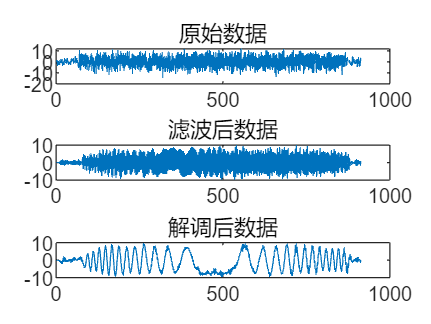

%调用六阶带通滤波器
filted_data_1=f_bandpassfilter(f0-B/2,f0+B/2,fs,rawdata1);
filted_data_2=f_bandpassfilter(f0-B/2,f0+B/2,fs,rawdata2);

%调用解调函数
base_band_1 = f_baseband(f0,tr,filted_data_1);
base_band_2 = f_baseband(f0,tr,filted_data_2);

%绘制
figure; hold on;
    subplot(3,1,1);
    plot(real(rawdata1(1,:)));
    title("原始数据");
    subplot(3,1,2);
    plot(real(filted_data_1(1,:)));
    title("滤波后数据");
    subplot(3,1,3);
    plot(real(base_band_1(1,:)));
    title("解调后数据");
hold off;

## 时延估计

- 主要采用滑动汉明窗实现，对汉明窗内出现的信号都计算延迟，并求平均。

- 保证汉明窗长度大于滑动步长，滑动出现重叠。

- i：信号数。

- j：汉明窗滑动次数。

windowLen = 8;         %窗长
stepLen = 4;           %步长
window_start = 1;      %窗起始点

%创建汉明窗
window = hamming(windowLen)';

for i=1:rows
   
    signal1 = base_band_1(i,:);
    signal2 = base_band_2(i,:);
    
    delay_temp = zeros(1,floor((cols-windowLen)/stepLen)+1);
    
    for j=1:(floor((cols - windowLen) / stepLen) + 1)
        
        %部分信号
        sig1 = signal1(window_start+(j-1)*stepLen:window_start+(j-1)*stepLen+windowLen-1);
        sig2 = signal2(window_start+(j-1)*stepLen:window_start+(j-1)*stepLen+windowLen-1);
        
        %加窗
        sig1 = sig1 .* window;
        sig2 = sig2 .* window;
    
        %FFT
        sig_fft1 = fft(sig1);
        sig_fft2 = fft(sig2);
        
        %计算相位
        phase_diff = angle(sig_fft2)-angle(sig_fft1);

        % 将相位差限制在 [-pi, pi] 范围内
        phase_diff = mod(phase_diff + pi, 2*pi) - pi;

        % 计算频率
        f = (0:windowLen-1)*(fs/windowLen); % 频率向量

        % 计算时延
        delay_f = phase_diff ./ (2 * pi * f); % 在每个频率下的时延
        delay_f(f == 0) = 0; % 处理 DC 分量

        % 计算平均时延
        delay_temp(j) = mean(delay_f); % 忽略 NaN 值
    end
    delay(i) = mean(delay_temp);
end

## 绘图

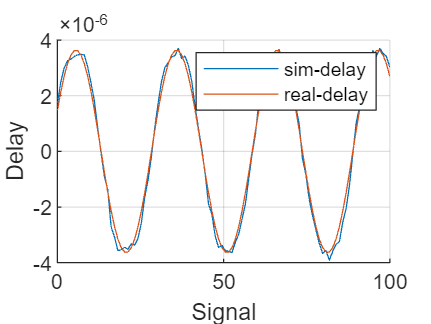

figure;hold on; grid on;
plot(linspace(0, rows, rows), -1*delay, 'DisplayName', 'sim-delay');
plot(linspace(0, rows, rows), tau_true, 'DisplayName', 'real-delay');
legend;
xlabel('Signal');
ylabel('Delay')
hold off;